# Lecture 9 Optical Ranging - Active

## 1. Structured light

### 1.1 Line scanning and stereovision

The most simple structred light ranging is line scanning method, where a line of the beam is projected to the scene. The resulting reflection of the objects is from the illumination line. The reflected light can then be detected by a camera that is separated from the projector with a baseline offset. The location on the camera image can be back projected and found by the same methods of triangulation. The geometry is equivalent to the stereovision we covered in Lecture 8. The only difference is that this point to point correspondence is established with a source and a detector, instead of two detectors.

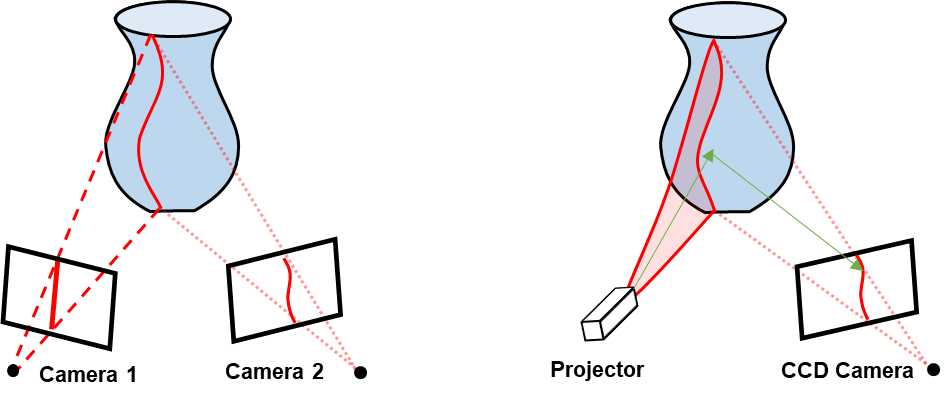

**ILL. 1.1 ***Triangulation geometry for both stereovision (left) and structural projection (right)*

Compared to stereovision, line scanning has the advantages of eliminating the ambiguity from correspondence matching. For stereovision cameras, the correspondence is established by feature matching algorithm between the two views, which could results in non-unique maching. Consider a structured light using a single (pencil) beam, where only one bright spot is observed on the detector, establishing a unique correspondence. A line scanning can improve the imaging speed, as long as the projected line is not parallel to the epipolar line.  For example, in ILL. 1.1 (right) the epipolar line of the camera and the illumination lie in the horizontal plane, and a vertical line is projected to the object. Based on the vertical location, one can find correspondence of each point on the projection line.

***Example 1.1a ***

Structured light line scanning of a teapot: In this example, 128 scan lines are sequentially projected to the 'teapot'. The teapot has a dimension roughly about 3 cm x 3 cm x 3 cm. The projector and camera are placed ~ 50 cm away, with a separation ~ 10 cm. 

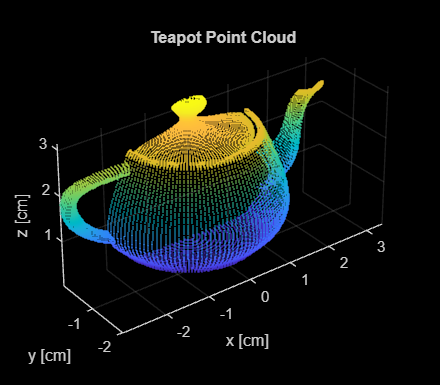

ptCloud_full = pcread('teapot.ply');
% only use half of the full surface
xyzPoints_n = ptCloud_full.Location(ptCloud_full.Location(:,2)<0,:);
ptCloud = pointCloud(xyzPoints_n);
figure;
set(gcf,'Position', [100 100 400 350])
pcshow(ptCloud) % coordinate is in cm
title("Teapot Point Cloud")
xlabel("x [cm]")
ylabel("y [cm]")
zlabel("z [cm]")

% line projection
f = 1; % focal length of projection and detection [unit: cm]
xp_0 = 0; % x,z coordinates of the principle point of the projector
yp_0 = 50; % projector is 50 cm away from the object
zp_0 = 0;
% object location
ptc_x = ptCloud.Location(:,1);
ptc_y = ptCloud.Location(:,2);
ptc_z = ptCloud.Location(:,3);

rp = [ptc_x-xp_0,ptc_z-zp_0,ptc_y-yp_0,ones(length(ptc_z),1)];  
% object homogenous coordinates on projector
Kp = [-f, 0, 0, 0;
      0, -f, 0, 0;
      0, 0, 1, 0];
wp = rp*Kp';
up = wp(:,1)./wp(:,3);
vp = wp(:,2)./wp(:,3);

% sort the projection direction
resu = 128; % projection resolution in u direction

uEdge = linspace((ptCloud.XLimits(1)-xp_0).*f/yp_0,...
    (ptCloud.XLimits(2)-xp_0).*f/yp_0, resu); 
du = uEdge(2)-uEdge(1);

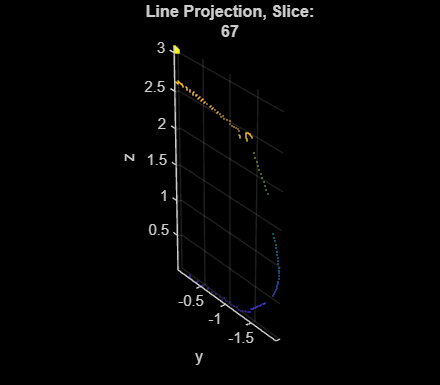

[n,~,binU] = histcounts(up,uEdge); 
[unq_BinU,~,binIDU] = unique(binU,'rows');
proj_slide = 67; 
% show the slides that is illuminated
proj_xyz = ptCloud.Location(binU==unq_BinU(proj_slide),:);
proj_ptc = pointCloud(proj_xyz);
% show the line projection part of the point cloud
figure;
set(gcf,'Position', [100 100 400 350])
pcshow(proj_ptc);
title(["Line Projection, Slice:" proj_slide])
xlabel("x")
ylabel("y")
zlabel("z")

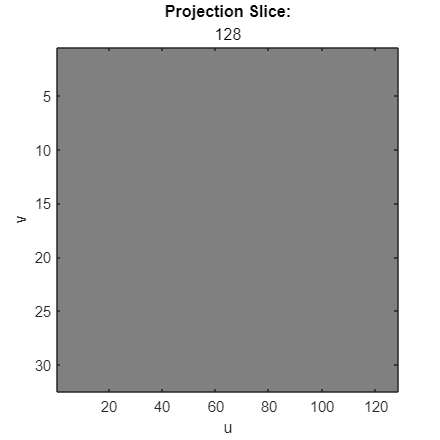

% detection of a series of images
xd_0 = 10; % x,z coordinates of the principle point of the imager
yd_0 = 50; % imager is 50 cm away from the object
zd_0 = 0;
rd = [ptc_x-xd_0,ptc_z-zd_0,ptc_y-yd_0,ones(length(ptc_z),1)];  

% object homogenous coordinates on detection
Kd = [-f, 0, 0, 0;
      0, -f, 0, 0;
      0, 0, 1, 0];
wd = rd*Kd';
ud = wd(:,1)./wd(:,3);
vd = wd(:,2)./wd(:,3);

resv = 32; % projection resolution in v direction
udEdge = linspace((ptCloud.XLimits(1)-xd_0).*f/yd_0,...
    (ptCloud.XLimits(2)-xd_0).*f/yd_0, resu);
vdEdge = linspace(ptCloud.ZLimits(1)-zd_0.*f/yd_0,...
    (ptCloud.ZLimits(2)-zd_0).*f/yd_0,resv); 
dv = vdEdge(2)-vdEdge(1);
% collected image series
Img_series = zeros(resu,resv,resu);
for ii = 1:length(unq_BinU)
    indx = binU==unq_BinU(ii); % pick the projected line
    proj_ud = ud(indx);
    proj_vd = vd(indx);
    [n2d,~,~,binUd,binVd] = histcounts2(proj_ud, proj_vd, udEdge, vdEdge); 
    [unqBins,~,binIDs] = unique([binUd,binVd],'rows');
    A = zeros(resu,resv);
    ind = sub2ind(size(A),unqBins(2:end,1),unqBins(2:end,2)+1);    
    A(ind) = 1;
    Img_series(:,:,unq_BinU(ii))=A;
end
% show projection measurement
figure;
set(gcf,'Position', [100 100 400 400])
colormap("gray")

for ii = 1:resu
    img = squeeze(Img_series(:,:,ii));
    imagesc(rot90(img))
    title("Projection Slice:", ii)
    xlabel("u");ylabel("v");
    pause(0.1)
end

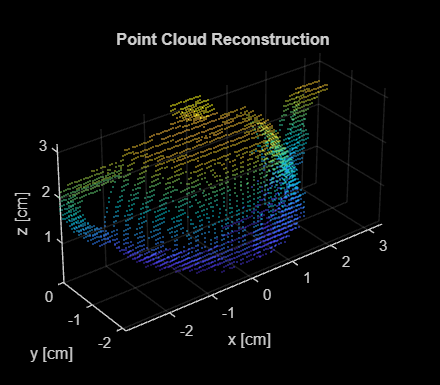

% point cloud reconstruction 
ptc_r = []; % reconstructed point coordinates
for ii=1:resu
    B = squeeze(Img_series(:,:,ii));
    [row,col]=find(B);
    ptc_y_r = f.*(xp_0-xd_0)./(uEdge(ii)-udEdge(row)); % triangularion
    ptc_x_r = (uEdge(row)+xp_0)./(-f).*ptc_y_r;
    ptc_z_r = (vdEdge(col)+zp_0)./(-f).*ptc_y_r;
    ptc_r_add = [ptc_x_r;ptc_y_r+yd_0;ptc_z_r]; % new points added
    ptc_r = [ptc_r;ptc_r_add'];
end

ptc_recon = pointCloud(ptc_r);
figure()
set(gcf,'Position', [100 100 400 350])
pcshow(ptc_recon) % coordiate is in cm
title("Point Cloud Reconstruction")
xlabel("x [cm]")
ylabel("y [cm]")
zlabel("z [cm]")

Feel free to rotate the 'teapot' to see the depth discretization of this reconstruction.

**Ranging resolution:**

The resolution of ranging is determined by the triangulation geometry, which is the same as stereovision camera.

The depth inferred from triangulation:


$$z=f\frac{b}{d}$$


where $f$ is the focal length, $b$ is the baseline separation of the projector and camera lenses' principal points, and $d$ is the disparity. If the disparity has an error of $\delta d$,then this introduces the triangulation error


$$\delta z=\frac{z^2 }{\textrm{fb}}\delta d$$


$\delta d$ is usually on the same order of the detector pixel size/PSF size of the projection or detection system. From this equation, we can see that with the same system ($\delta d,f,b$ are fixed), the further the object is, the worse the resolution. For the Example 1.1, $b=$10 cm, $f=$1 cm, the triangulation error $\delta d$ is ~ 10 $\mu m$, $z=$50 cm. Then $\delta z=\frac{{50}^2 }{10\textrm{x1}}$10 $\mu m=2\ldotp 5\;\textrm{mm}$. You can see that the depth ia roughly discretized with such a step size.

### 1.2 Patterned structured light ranging

However, since the line scanning is used, the full field imaging would take a series of images, each corresponding to a column, resulting a slower aquisition time snapshot in stereovision. 

This is a good place to introduce the concept of multiplexing: the technique of simultaneously measuring multiple signals or parameters using reduced measurements. This is achieved by combining or encoding the signals in such a way that they can be measured at once, and then separated or decoded after the measurement. Multiplexing is a widely-used concept in various engineering and science domains, primarily to maximize the utilization of available resources (like bandwidth or channels) and reduce costs and complexities.

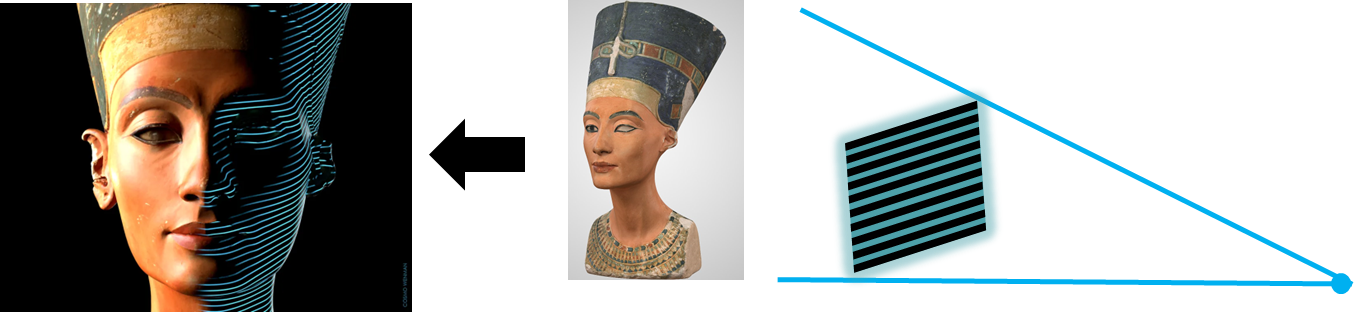

**ILL. 1.2 ***Patterned structured light for ranging (image source: *[*https://slate.com/technology/2019/11/nefertiti-bust-neues-museum-3d-printing.html)*](https://slate.com/technology/2019/11/nefertiti-bust-neues-museum-3d-printing.html))

For structured light, instead of projecting one line at a time, an **encoded** pattern is projected onto a surface can greatly improve the imaging throughput. A set of encoded illumination is designed so that the camera captured projection can be easily matched to decompose the projection to line-projection. The process of matching an image region with its corresponding pattern region is known as pattern **decoding**. Decoding a projected pattern allows a large set of correspondences to be easily found thanks to the prior knowledge of the light pattern. 

Take the periodic binary pattern encoding shown in ILL. 1.3, as an example, the projection is a series of periodic binary pattern, which include the same amount of information as the series of line projection.

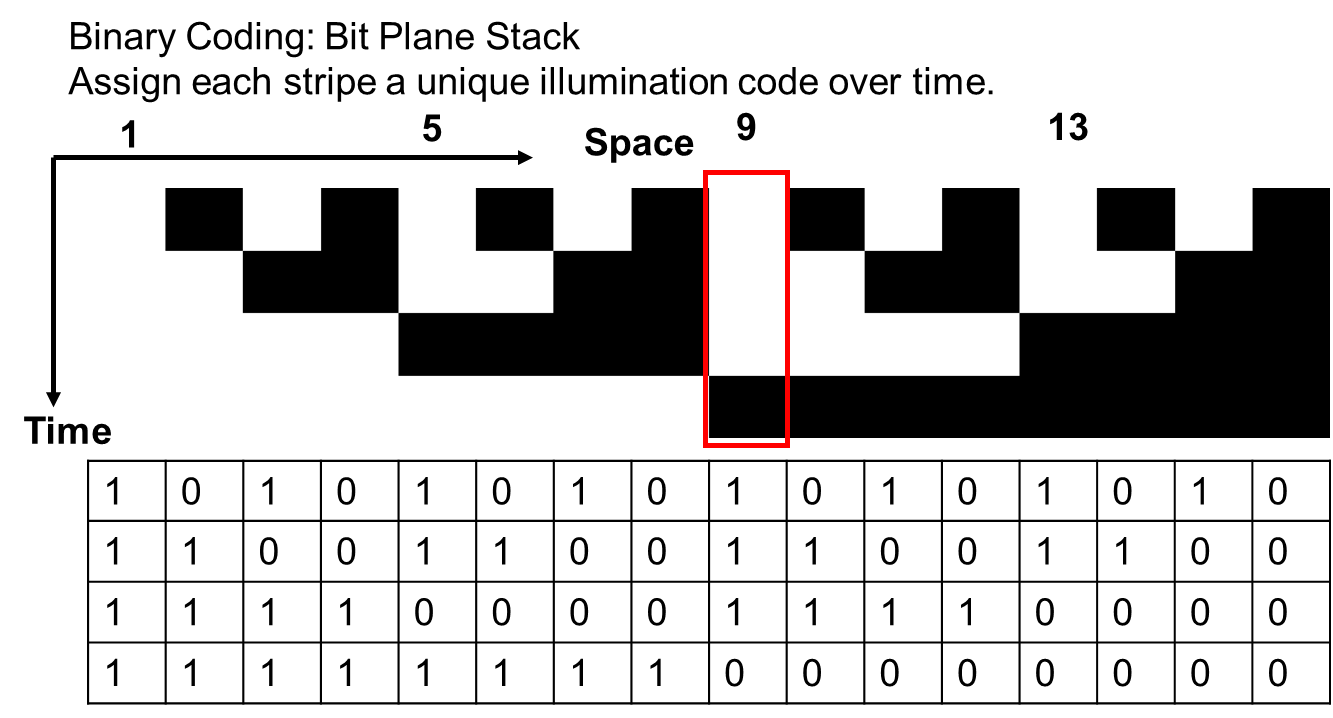

**ILL. 1.3 ***Binary encoding of the illumination pattern*

The temporal code ($0/1\to \textrm{dark}/\textrm{bright}$) can uniquely determine the corresponding spatial projection. For example, pattern ($\textrm{b1110}$) corresponds to location 9 for the spatial pattern. To fully locate all 16 locations, only $\textrm{log2}\left(16\right)=4$ multiplexed measurements are needed, instead of using a 16-line scan series.

**For binary coding:**

Only 0 and 1 are used for illumination levels. Every encoded location is identified by the temporal sequence of intensities. N projected patterns can encode $2^n$ spatial locations. Instead of simple periodic code, Gray code (adjacent strips must only differ in 1 bit) is often used for more robust measurement.

***Example 1.1b ***

Reconstruction: This example only shows the generation of measurement from periodic binary projection. We encourage the interested readers to decode(demultiplex) the measurements and reconstruct the point cloud.

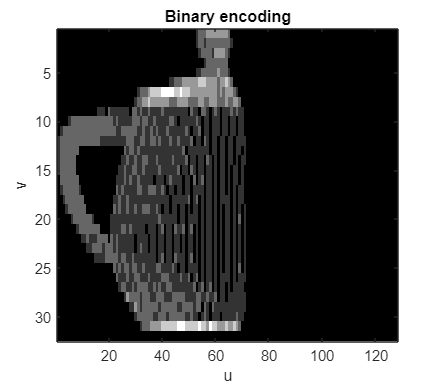

% forming binary pattern measurement
n_p = log2(resu); % binary pattern encoding bit
Img_series_bin = zeros(resu,resv,n_p);

for ii = 1:n_p
    [p_row, p_col]=ndgrid(1:(2^(ii-1)),1:(2^(n_p-ii)));
    indx = sub2ind([2^ii,2^(n_p-ii)],p_row,p_col);
    Img_series_bin(:,:,ii) = sum(Img_series(:,:,indx(:)),3);
end
% plot the encoded projections
figure;
colormap('gray');
for ii = 1:n_p
    snap = squeeze(Img_series_bin(:,:,ii));
    imagesc(rot90(snap))
    title("Binary encoding");
    xlabel("u");ylabel("v");
    set(gcf,'Position', [100 100 400 350]);  
    pause(0.5)
end

### 1.3 Other encoding strategies

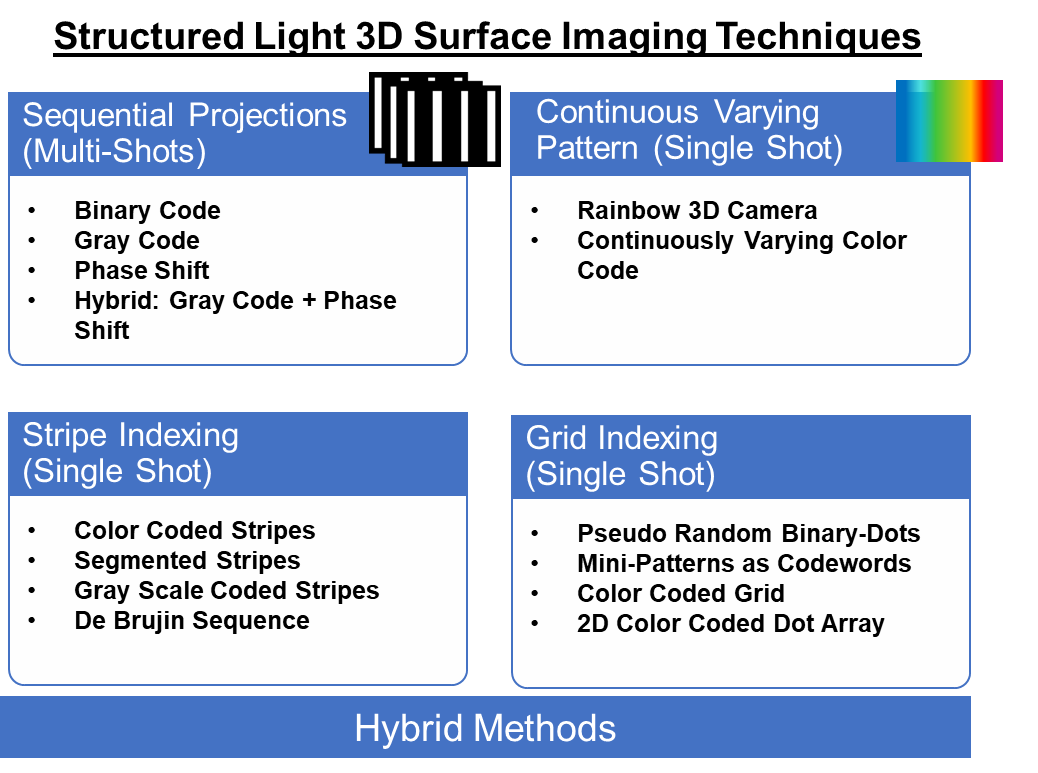

**ILL 1.4 ***Structured Light Surface Imaging Techniques adapted from J. Geng, Structured-light 3D surface imaging: a tutorial, ****Advances in Optics and Photonics*** *Vol. 3, (2011).*

**A Hybrid Example:**

The Kinect combines structured light with two classic computer vision techniques: depth from focus and depth from stereo vision. The speckle pattern is created with an infrared laser, serving as structured light. Like the line/binary structured light mentioned earlier, the structured speckles were calibrated, and the local displacement of the pattern contains the depth information. 

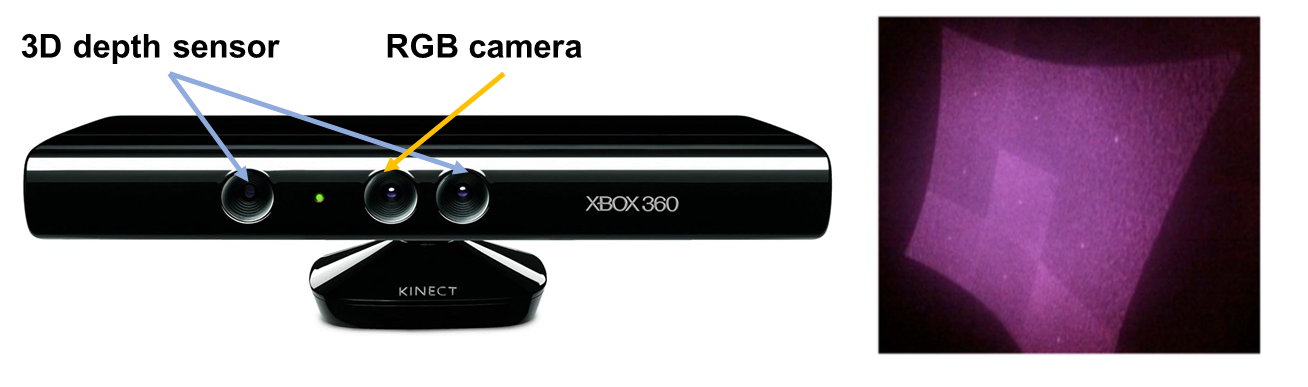

**ILL. 1.5** *A hybrid ranging example: Microsoft Kinect Xbox 360 with its IR laser speckle pattern.*

## **2. Time of flight**

LiDAR (Light Detection and Ranging) is a remote active ranging and sensing method. The light source (laser or incoherent sources) send a temporally varying illumination. By measuring the reflection sequence, the distance can be determined. The temporal encoding includes a variety of methods, we focus on two common types: Time of flight (ToF) and frequency modulated continuous wave (FMCW) ranging, shown in ILL. 2.1.

Specifically, for ToF ranging, a modulated light emits from the transmitter and travels outward and strikes an object, e.g., ground, trees, or buildings. A portion of the light pulse is reflected backtowards the source and detected by a receiver. The amount of light that comes back can depend on the properties of the object and the beam diffraction. The LiDAR measures the time it took for the light pulse to travel to the object and back, and the distance can be simply determined by:


$$z=\frac{c\tau }{2}$$


The division by 2 accounts for the round-trip time. 

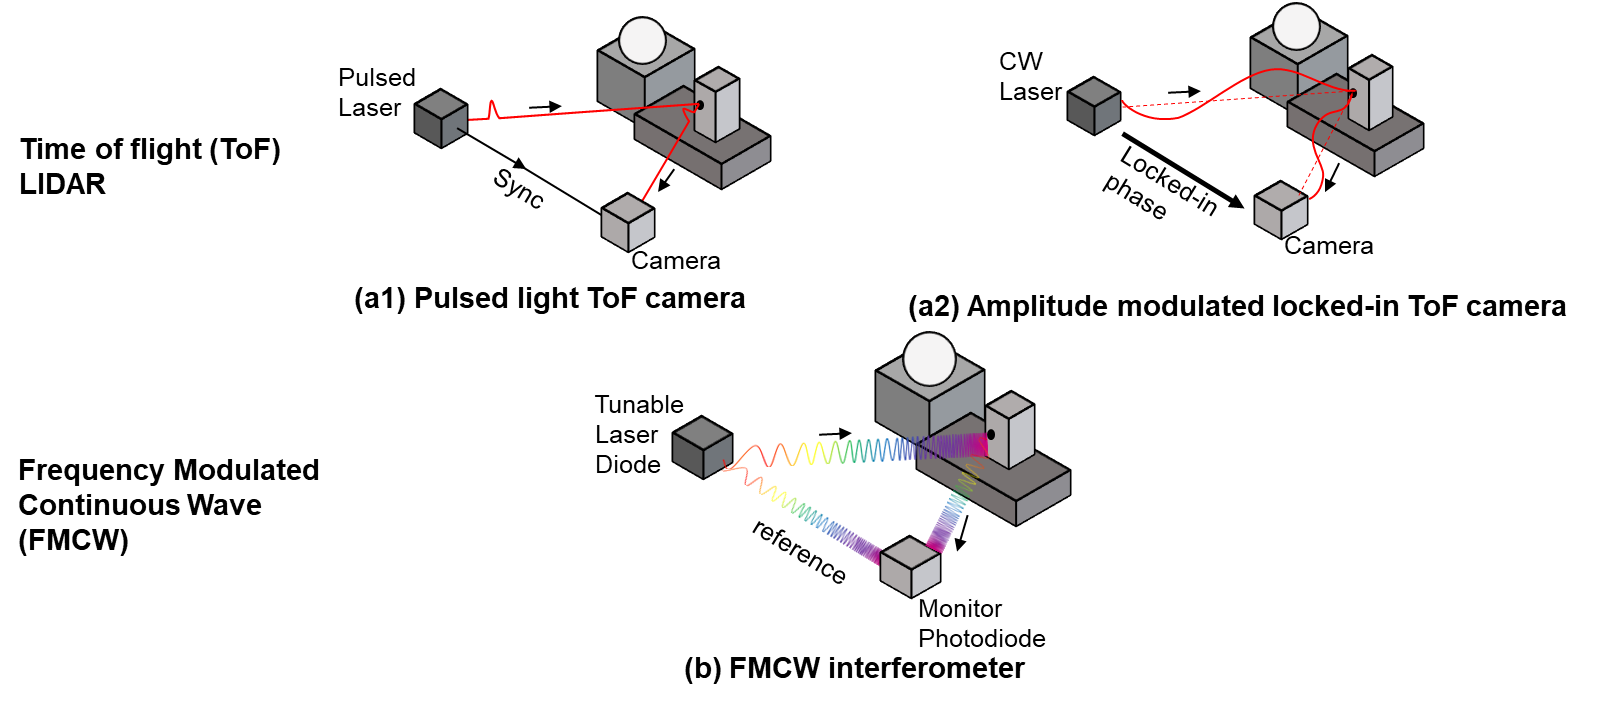

**ILL. 2.1 ***Illustrations of common LIDAR operating principle*

### 2.1 Pulsed light

Pulsed light is the most common type of temporal encoding, shown in ILL. 2.2. The LiDAR system typically emits and receives many pulses per second, collecting a large number of data points. Each of these data points represents a distance measurement to a specific point on the ground or object. Collectively, these points form the point cloud.

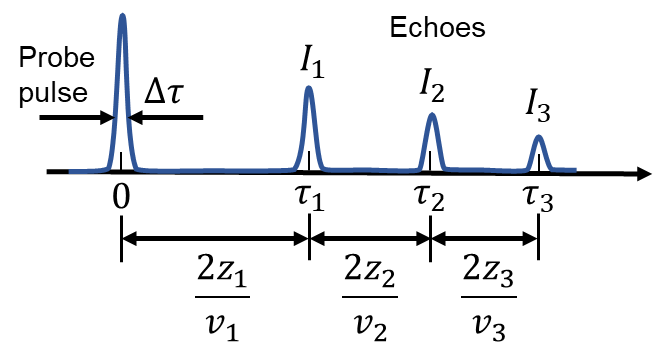

**ILL. 2.2 ***Pulsed light travels outward towards the objects, and each reflected pulse (echos) with different time delay are detected by the receiver.*

The distance of each reflective surface can be calculated by


$$\tau_1 =\frac{2z_1 }{c},\tau_2 =\frac{2z_2 }{c},\tau_3 =\frac{2z_3 }{c}\ldotp$$


The key benefit of pulsed LiDAR, especially when compared to continuous-wave LiDAR, is its ability to measure distances to multiple objects in the path of a single pulse. This characteristic makes it particularly useful for tasks like mapping forest canopy structure or identifying multiple layers of ground cover.

**Depth resolution and precision of pulsed ToF LiDAR:**

Similar to our discussion in lateral spatial resolution, we know that the temporal locality is related to the precision of ToF ranging. However, we need to clarify that the ranging problem is a little different from determining the resolution. **Resolution** is defined by the smallest (temporal) separation between two detected return waveforms that we can still distinguish the pulses. **Precision** is how accurately we can determine the centroid of the return waveforms. 

Resolution is determined by both the detection temporal resolution $\delta \tau_{\det }$ and the illumination pulse duration $\delta \tau_{\textrm{pulse}}$ . The response waveform also has a temporal span $\delta \tau$ . Assuming these are two uncorrelated Gaussian distributions,


$$\delta \tau =\sqrt{\delta \tau_{\det }^2 +\delta \tau_{\textrm{pulse}}^2 }$$


Consider a pulse width of 100 picosecond, and a detection photodiode with a bandwidth of 1 GHz ( $\delta \tau_{\det } \approx$1 nanosecond). $\delta \tau \approx$1 ns, given a standard deviation (i.e., spread) of the range measurement $\sigma_z =\frac{c}{z}\delta \tau =$15 cm. To determine the precision, we need to mention the quantized nature of detection.

**Photon Detection**

As the photons are absorbed by the photo detector, photoelectrons driven by the bias voltage forms photocurrent. Photon counting detection with time resolved circuits using a time-to-digital converter (TDC) records an individual photon that falls into a specific ‘time bin’. Using a photon-counting detector, the return pulse will no longer be an analog waveform of photocurrent but a digital one that registers when at least one photon gets detected. The time measurement precision is limited by the time-to-digital converter’s step size, which is typically greater than 50 ps. 

If we assume the echo photon delay time follows Gaussian distribution, with its peak at $\tau_0$, then


$$p\left(t\right)=\frac{1}{\sqrt{2\pi }\delta \tau }\exp \left(-\frac{1}{2}{\left(\frac{t-\tau_0 }{\delta \tau }\right)}^2 \right)$$


And the expected value


$$E\left\lbrack t\right\rbrack =\tau_0$$


If we detected N photons, each time at $t_1 ,t_2 ,\ldotp \ldotp \ldotp ,t_N$, respectively. The arrival time $\bar{t} =\frac{1}{N}\sum_{i=1}^N t_i$ has an expected certainty of


$$\sigma_{\bar{t} } =\frac{\delta \tau }{\sqrt{N}}$$


By detecting hundreds and thousands of the photonics, the precision of range measurement can reach to even sub TDC step size. *Example  2.1* demonstrates this process with a $\delta \tau =$ 1 ns, and TDC time bin size $\Delta t=$ 50 ps. Please change the number of detected photons to see the detection precision.

***Example 2.1 ***

ToF delay estimation based on return photon statistics following a normal distribution. From this example, we can see that sub-time bin (<50 ps) accuracy can be achieved. This is equivalent to a distance precision on the order of mm.

n = 3; % log2 of detected photon number

Please click the button below to see the histograms of n-photon arrival time of multiple instances. 

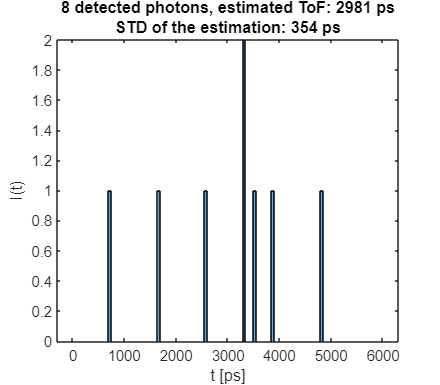

  
N = 2^n; % number of photons detected. 
tau0 = 3e3; % return pulse bias [Unit: ps]
dtau = 1e3; % sigma of return distribution [Unit: ps]
dt = 50; %
nbin_sig = round(dtau/dt); % # of bin corresponding to 1 sigma
edges = tau0+(-3*nbin_sig:3*nbin_sig)*dt;
t = tau0+dtau*randn([N,1]);

h = histogram(t,edges);
set(gcf,'Position', [100 100 400 350])
t_est = dot(h.BinEdges(1:end-1),h.BinCounts)./N+dt/2; 
sig_t_est = dtau/sqrt(N);
title([num2str(N), ' detected photons, estimated ToF: ',num2str(round(t_est)), ' ps', ...
    newline ,'STD of the estimation: ',num2str(round(sig_t_est)), ' ps']);
xlabel("t [ps]")
ylabel("I(t)")

### 2.2 Locked-in ToF camera

The locked-in ToF usually refers to using amplitude modulated continuous wave. Different from pulsed light ToF camera, locked-in ToF camera measures the locked-in phase differences between emitted and received signals (see ILL. 2.3) by using demodulation lock-in pixels. There are also many commercially available lock-in ToF cameras, mainly equipped with near-infrared (NIR) light-emitting diode (LED) illumination, lowering the cost compared to pulsed laser system. Many literature uses the formulations of sinusoidal signals. Though in practice other periodic functions are often used. By sampling a small number of intensity on the sinusoidal signal, the phase (ToF delay) can be calculated. Specifically, every pixel on the sensor samples the amount of light reflected by the scene four times at equal intervals for every sinusoidal period ($t_0 ,t_1 ,t_2 ,\textrm{and}\;t_3$ in ILL. 2.3)

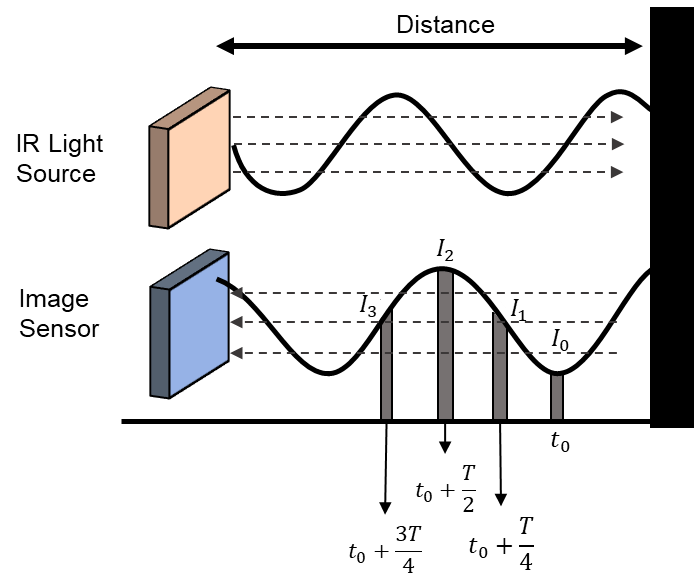

**ILL. 2.3*** Locked-in ToF sensor measures the phase delay of the modulation*

The offset of the sinusoidal signal is


$$b=\frac{I_0 +I_1 +I_2 +I_3 }{4}\ldotp$$


The amplitude is


$$A=\frac{\sqrt{{\left(I_3 -I_1 \right)}^2 +{\left(I_0 -I_2 \right)}^2 }}{2}\ldotp$$


The phase is


$$\phi =\tan^{-1} \left(\frac{I_3 -I_1 }{I_0 -I_2 }\right)\ldotp$$


The range estimated from the phase is

$z=\frac{c\tau }{2}=\textrm{cT}\frac{\phi }{4\pi }$.

Where $\tau$ is the ToF and $T$ is the modulation sinusoidal period.

In *Example 2.2*, we use a radio frequency (RF) modulation of 20 MHz ($T=$ 50 ns). The sampling period $\frac{T}{4}=$12.5 ns. We can use 4-point amplitude measurement to determine the ToF delay.

***Example 2.2: ***

Locked-in pixel calculation of ToF delay

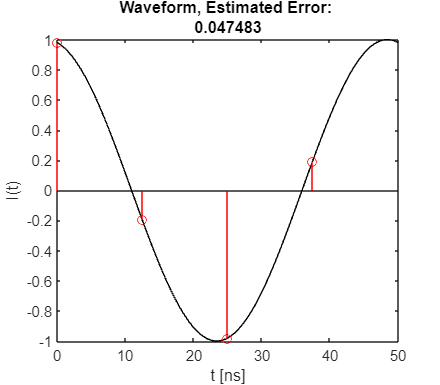

freq = 20; % amplitude modulation frequency [Unit: MHz]
T = 1/freq*1e3; % period of RF modulation [Unit: ns]
nt = 1024;
t_min = 0; % time delay lower bound [Unit: ns]
t_max = 50; % time delay upper bount [Unit: ns]
t = linspace(t_min,t_max,nt); % time axis
dt = t(2)-t(1);
n_T = round(T/dt);% index corresponding to one period.
tau0 = 1.6; % ToF delay, [Unit: ns]
I = cos(2*pi*freq*(t+tau0)./1e3);
ind_s = [1, round(n_T/4), round(n_T/2), round(n_T*3/4)]; % sampled index
t_s = t(ind_s);
I_s = I(ind_s);
% estimate the ToF
phi_est = atan((I_s(4)-I_s(2))/(I_s(1)-I_s(3)));
tau0_est = phi_est/2/pi*T;

% plot the waveform
figure()
set(gcf,'Position', [100 100 400 350])
plot(t,I,'k'); hold on
stem(t_s, I_s,'r');
title(["Waveform, Estimated Error: " tau0-tau0_est])
hold off
xlabel("t [ns]")
ylabel("I(t)")

As the amplitude is modulated by a sinusoidal wave, the range of the depth measurement is limited by the wavelength of the RF modulation. In this case $Z_{\max } =\frac{c}{2}T=$ 15 m. Which is not very large. Using multiple modulation frequency can increase the range. 

From the results, we see a very good ToF estimation (< 100 ps). However, this is because we have not taken the measurement error into consideration. Particularly, Measurement accuracy and time sampling consistency affects the precision of the phase measurement.

**Measurement Accuracy**, which is the precision of the amplitude measurements ($\delta I$) at each point directly affects phase estimation accuracy. Any error in amplitude measurement can lead to an incorrect phase estimation. 

**Time Interval Consistency; **If the time sampling of the four measurements are not accurate ($\delta t_{\textrm{sample}}$), the intensity measured at these points can introduce error, leading to inconsistent phase calculation.

Since the phase delay calculation equation includes $\tan^{-1} \left(\cdot \right)$, the analytical formula of the uncertainty of ToF is not easy to derive. Yet this can be evaluated numerically. The interested readers are encouraged to include both errors ($\delta 1,\delta t_{\textrm{sample}}$) into the measurement and quantitatively determine the precision of locked-in ToFcamera.

## 3. Frequency modulated continuous wave

For frequency-modulated LiDAR, the laser frequency is modulated. It can be considered as an optical equivalent of frequency modulated continuous wave (FMCW) Radar. The achievable precision is typically better than in pulsed-LiDAR, with the major advantage of using low-bandwidth electronics and cost-effective detectors. Another advantage of FMCW-LiDAR is its ability to directly measure the velocity of the target object by extracting the Doppler-shift generated from the motion. The main limitation of FMCW is the demanding long coherence length of the laser, as it influences the stability of the local oscillator in respect to the backscattered wave, introducing phase-noise. If the measured distance is shorter than the laser coherence length, the peak of the beat-frequency spectrum results sharp and narrow, otherwise the peak widens and its amplitude decreases. 

### 3.1 FMCW LiDAR

Typically, the modulation consists of a linear chirp with a small portion of the laser beam (reference) used as local oscillator for the heterodyne demodulation of the return echo signal. The modulation bandwidth is often wider than the amplitude modulated method (e.g., locked-in ToF), yielding to improved depth resolution. 

### 3.2 FMCW interferometry

FMCW LiDAR emits a laser beam whose frequency is continuously varied over time in a known pattern, typically a sawtooth waveform as shown in ILL. 3.1.

The laser beam travels to an object and is reflected back towards the LiDAR system. The distance the light travels impacts the time it takes for the light to return. The LiDAR system receives the reflected signal. Due to the time taken for the light to travel to the object and back, there is a frequency difference between the emitted and received signals. 

**FMCW interferometry: extracting the beat frequency. **The key to FMCW LiDAR is in measuring this frequency difference, also known as the beat frequency, due to the time lag of the reflected light (Rx signal). Detection requires an optical heterodyne measurement to exploit the interference between emitted and backscattered optical waves to demodulate the return signal and generate a beat frequency, which can be recorded by a detection within the RF detection bandwidth. The distance to the object is determined by analyzing the beat frequency. The time of flight (the time taken for the light to travel to the object and back) is directly related to this frequency difference.

Because FMCW LiDAR measures the frequency difference (which can be done very precisely) rather than the time of flight, FMCW LiDAR can achieve higher resolution and sensitivity compared to traditional pulsed systems. In addition to distance, FMCW LiDAR can also measure the relative velocity of objects. The Doppler shift in the frequency of the reflected light provides information about the velocity of the object.

FMCW LiDAR is particularly useful in applications where high accuracy and resolution are required, such as autonomous vehicles, robotics, and atmospheric studies.

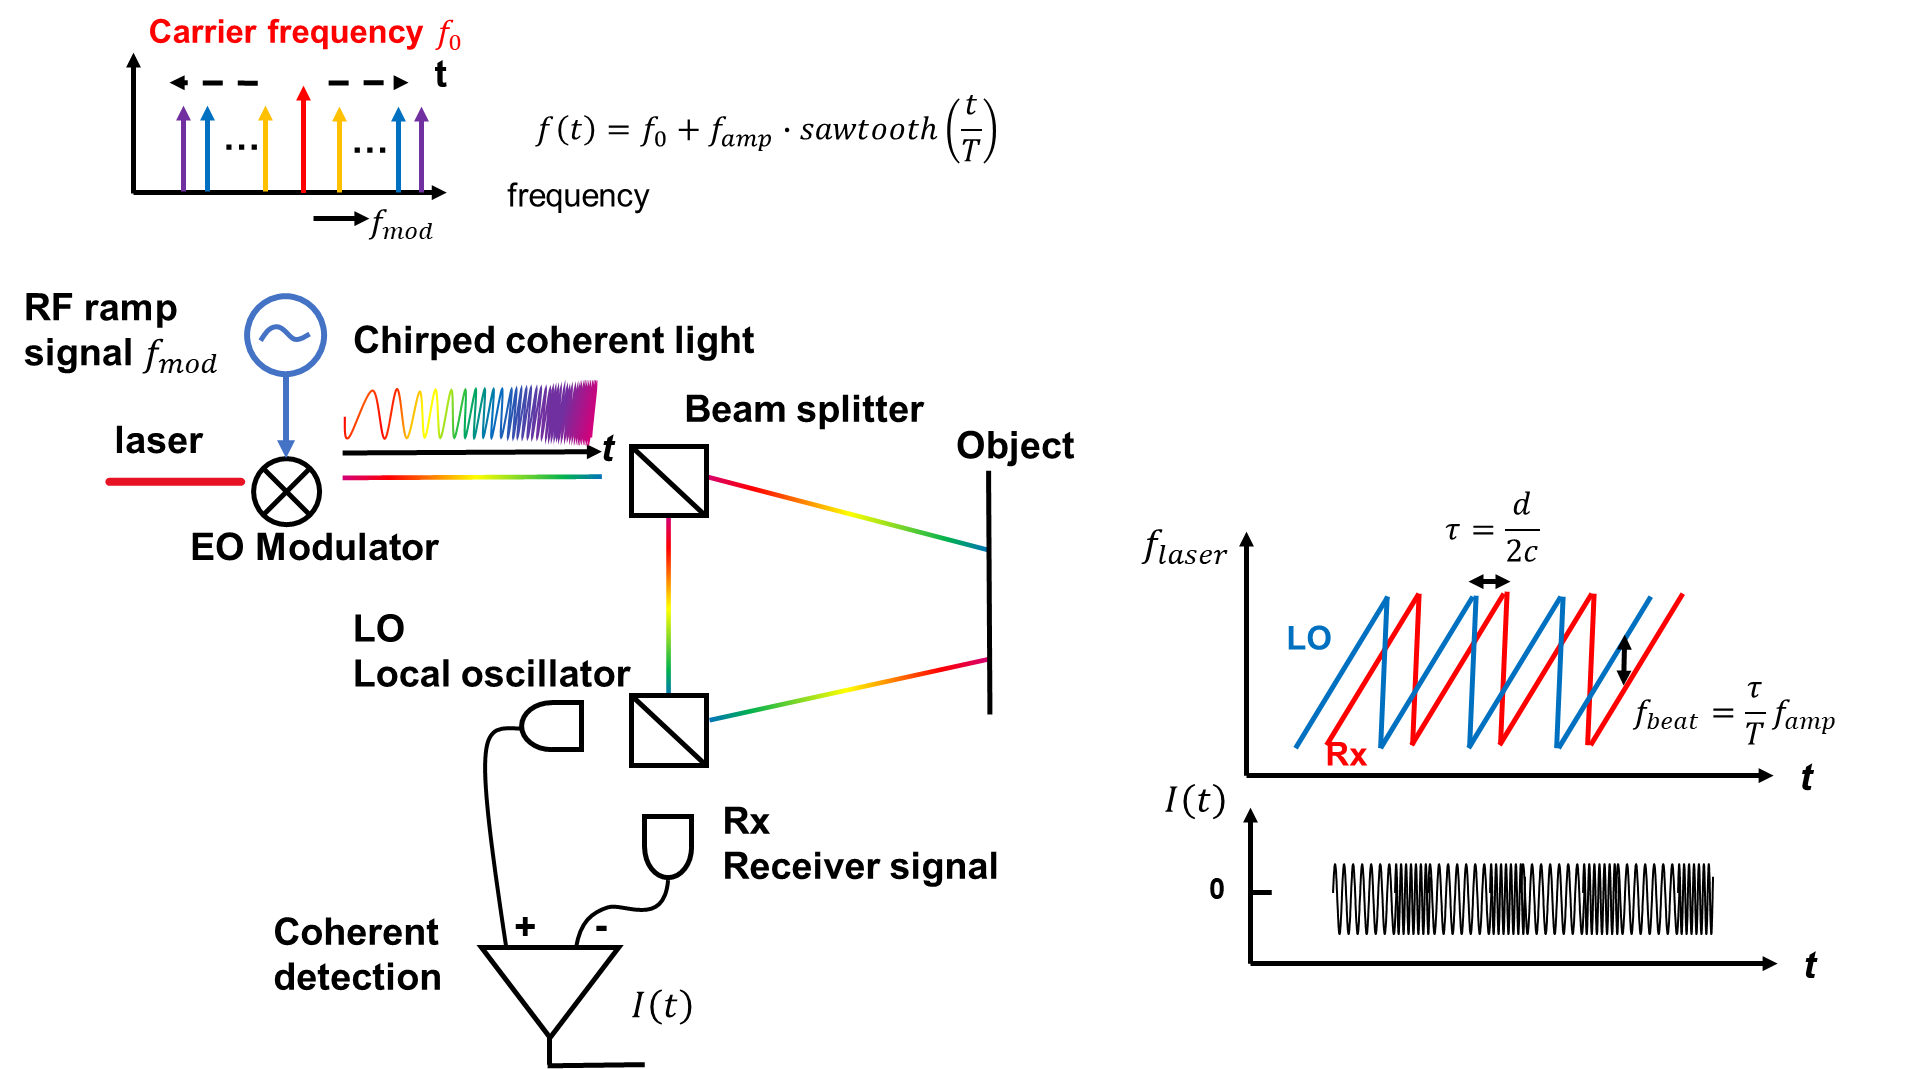

**ILL. 3.1 ***Schematics of the operating principle of FMCW LIDAR *

***Example 3.1***

FMCW interferometer generates beating signal in RF range.

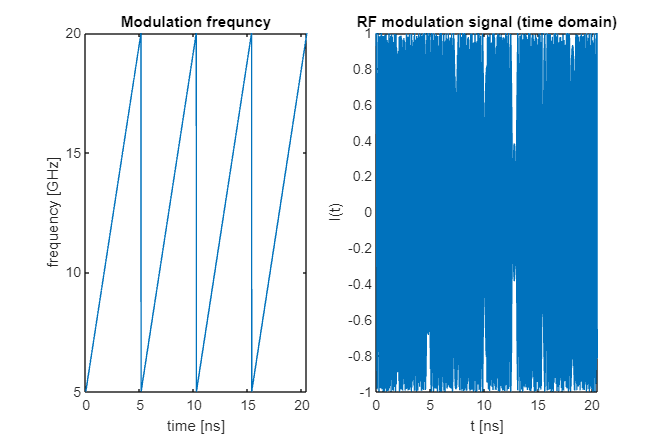

% continous wave freqeuncy modulated lidar
c = 3e8; % speed of light [Unit: m/s]
nt = 2048;
dt = 1e-2;% time step [Unit: ns]
t = dt*(0:nt-1); % the time
nc = 4;% number of cycles of the time span 
T = dt*nt/nc;
f_min = 5; % RF frequency modulation [Unit: GHz]
f_max = 20;
f_sweep = linspace(f_min,f_max,nt/nc);
f = repmat(f_sweep,[1,nc]);
E_ref = exp(1i*(2.*pi.*f.*t)); % Reference beam LO

figure;
set(gcf,'Position', [100 100 600 400])
subplot(121)
plot(t,f)
title('Modulation frequncy')
ylabel('frequency [GHz]')
xlabel('time [ns]')
subplot(122)
%plot(t(1:nt/nc),E(1:nt/nc));
plot(t,real(E_ref));
title('RF modulation signal (time domain)')
ylabel('I(t)')
xlabel('t [ns]')

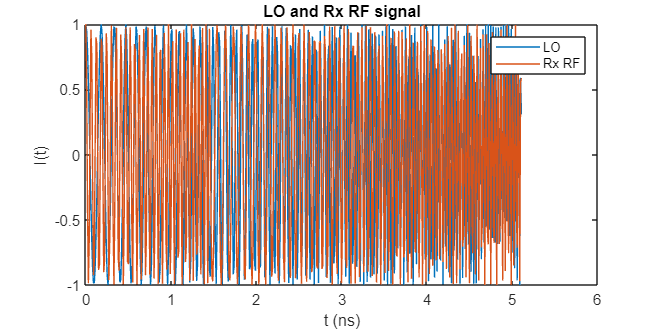

% introcucing delay
d = 0.22; %distance to target [Unit: m]
t_d = 2*d/c*1e9; % delay time [Unit: ns]
n_td = round(t_d/dt);
f_d = circshift(f,n_td); % delayed version of fm signal
r = 1; % reflectivity of the target
E_tar = r.*exp(1i*(2.*pi.*f_d.*t));
n_T = nt/nc;
% plot the LO and RX RF freqeuncy with respect to time 
figure;
set(gcf,'Position', [100 100 600 300])
plot(t(1:n_T),real(E_ref(1:n_T)),t(1:n_T),real(E_tar(1:n_T)));
title('LO and Rx RF signal');
xlabel("t (ns)")
ylabel("I(t)")
legend("LO", "Rx RF")

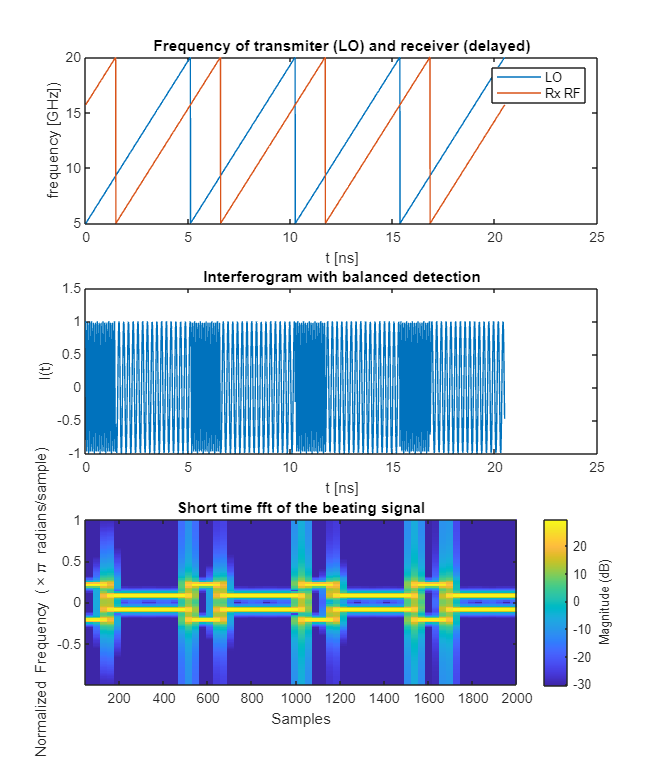

% interference of the signal
lambda0 = 1.55; % carrier wavelength [Unit: um]
f0 = c/(lambda0*1e-15); % carrier frequency [Unit: GHz] 
E_lo = E_ref.*exp(1i*2*pi*f0.*t);
E_rx = E_tar.*exp(1i*2*pi*f0.*t);
% balanced detection
I = real(E_lo.*conj(E_rx));
figure;
set(gcf,'Position', [100 100 600 700])
subplot(311) %plot 1
plot(t,f,t,f_d)
title('Frequency of transmiter (LO) and receiver (delayed)')
xlabel("t [ns]")
ylabel("frequency [GHz])")
legend("LO", "Rx RF")
subplot(312) %plot 2
plot(t,I);
title('Interferogram with balanced detection')
ylabel('I(t)')
xlabel('t [ns]')
subplot(313) %plot 3
stft(I,FFTLength=128); % short time fft show the frequency range
title('Short time fft of the beating signal')

**Depth resolution and precision of FMCW LiDAR**: 

For any time-of-flight ranging system based on either electromagnetic or ultrasonic waves, the range resolution can be found using the following equation:


$$\delta Z=\frac{c}{2B}$$


where $B$ is the bandwidth of the modulation.

The time difference between the reflections from two such targets is $\delta \tau =\frac{2\delta Z}{c}$, translating to a bandwidth inversely proportional to this time, or $B=\frac{c}{2\delta Z}$. The bandwidth of radio frequency waves can reach tens of GHz, resulting in sub-centimeter range resolution. Compared to Radar, optical carrier can support much larger bandwidth, enabling finer resolution. The precision vs resolution argument in pulsed ToF LiDAR also applies in FMCW LiDAR,  ranging precision is different is proportional to $\frac{\delta Z}{\textrm{SNR}}$ , where SNR is the signal-to-noise ratio of the received signal. This equation is consistent with the pulsed LiDAR equation $\frac{\delta Z}{\sqrt{\;N}}$, if the photon arrival follows Poisson distribution (i.e., $\textrm{SNR}=\sqrt{\;N}$). 